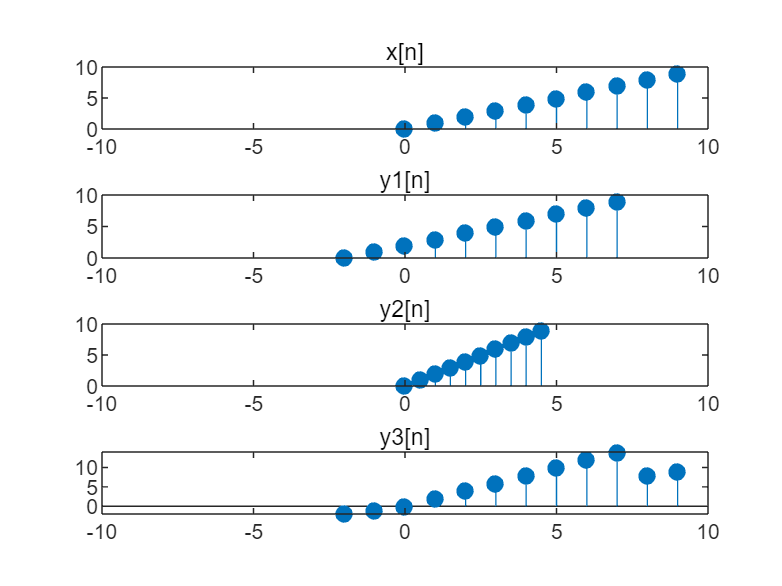

clc,clear,close all;
n = [0 1 2 3 4 5 6 7 8 9];
x = n;
ny3 = -2:1:9;
y3 = [0 0 0:1:9] + [-2:1:7 0 0];
figure
subplot(4,1,1),stem(n,x,'filled'),title('x[n]'),xlim([-10 10]);
subplot(4,1,2),stem(n-2,x,'filled'),title('y1[n]'),xlim([-10 10]);
subplot(4,1,3),stem(0.5*n,x,'filled'),title('y2[n]'),xlim([-10 10]);
subplot(4,1,4),stem(ny3,y3,'filled'),title('y3[n]'),xlim([-10 10]);

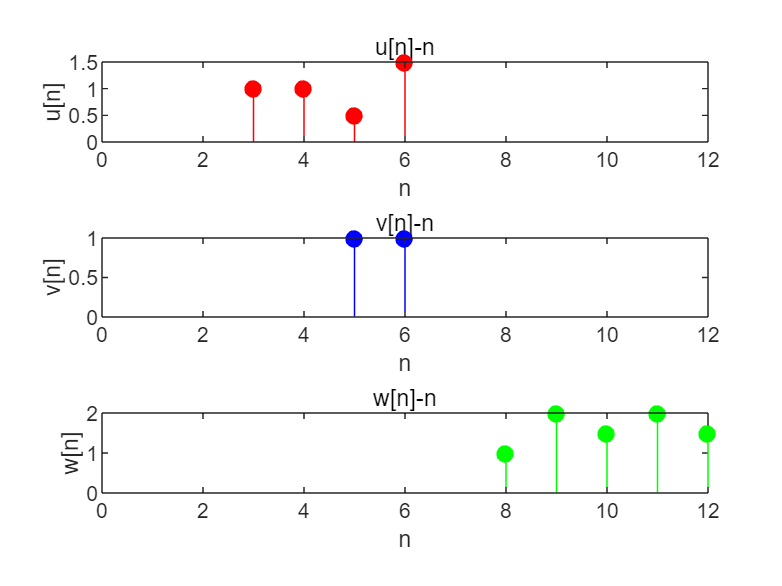

clc,clear,close all;
u = [1 1 0.5 1.5];
nu = 3:6;
v = [1 1];
nv = 5:6;
w = conv(u,v);
nw = nu(1) + nv(1) : nu(end) + nv(end);
figure
subplot(3,1,1),stem(nu,u,'r','filled'),title('u[n]-n'),xlim([0 nu(end) + nv(end)]),xlabel('n'),ylabel('u[n]');
subplot(3,1,2),stem(nv,v,'b','filled'),title('v[n]-n'),xlim([0 nu(end) + nv(end)]),xlabel('n'),ylabel('v[n]');
subplot(3,1,3),stem(nw,w,'g','filled'),title('w[n]-n'),xlim([0 nu(end) + nv(end)]),xlabel('n'),ylabel('w[n]');

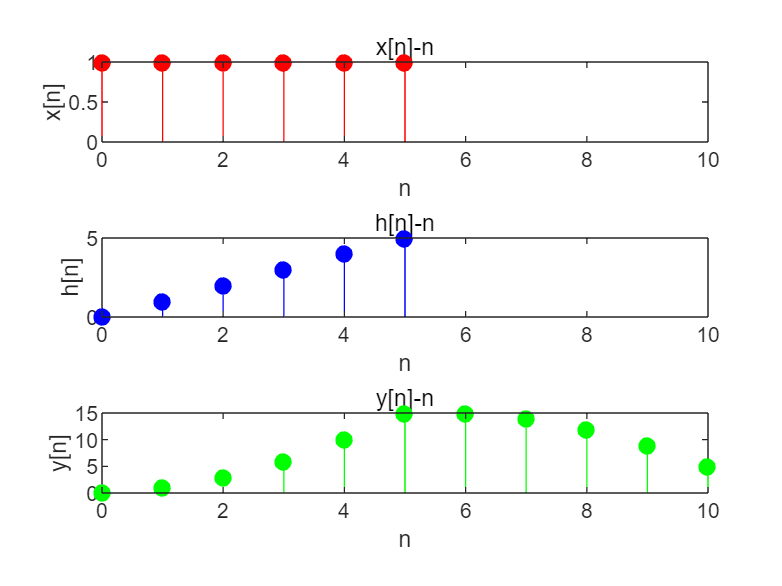

clc,clear,close all;
x = [1 1 1 1 1 1];
nx = 0:1:5;
h = 0:1:5;
nh = 0:1:5;
y = conv(x,h);
ny = nx(1) + nh(1) : nx(end) + nh(end);
figure
subplot(3,1,1),stem(nx,x,'r','filled'),title('x[n]-n'),xlim([0 nx(end) + nh(end)]),xlabel('n'),ylabel('x[n]');
subplot(3,1,2),stem(nh,h,'b','filled'),title('h[n]-n'),xlim([0 nx(end) + nh(end)]),xlabel('n'),ylabel('h[n]');
subplot(3,1,3),stem(ny,y,'g','filled'),title('y[n]-n'),xlim([0 nx(end) + nh(end)]),xlabel('n'),ylabel('y[n]');

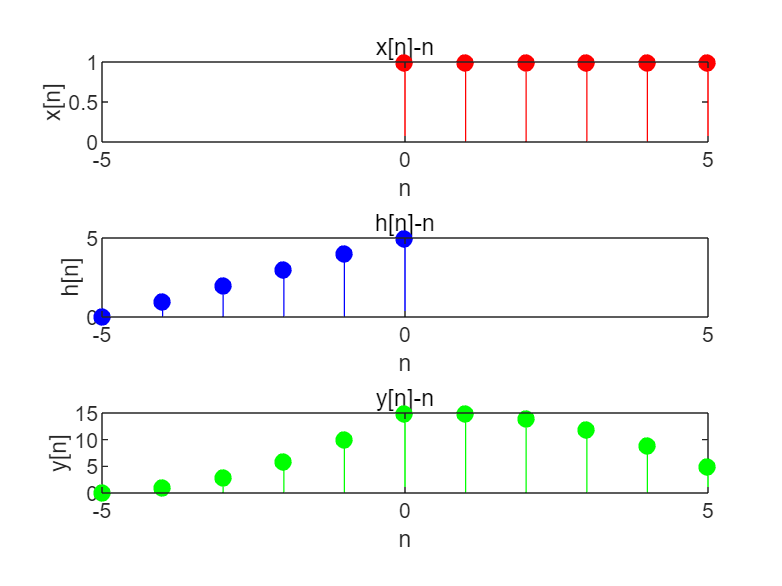

clc,clear,close all;
x = [1 1 1 1 1 1];
nx = 0:1:5;
h = 0:1:5;
nh = -5:1:0;
y = conv(x,h);
ny = nx(1) + nh(1) : nx(end) + nh(end);
figure
subplot(3,1,1),stem(nx,x,'r','filled'),title('x[n]-n'),xlim([nx(1) + nh(1) nx(end) + nh(end)]),xlabel('n'),ylabel('x[n]');
subplot(3,1,2),stem(nh,h,'b','filled'),title('h[n]-n'),xlim([nx(1) + nh(1) nx(end) + nh(end)]),xlabel('n'),ylabel('h[n]');
subplot(3,1,3),stem(ny,y,'g','filled'),title('y[n]-n'),xlim([nx(1) + nh(1) nx(end) + nh(end)]),xlabel('n'),ylabel('y[n]');

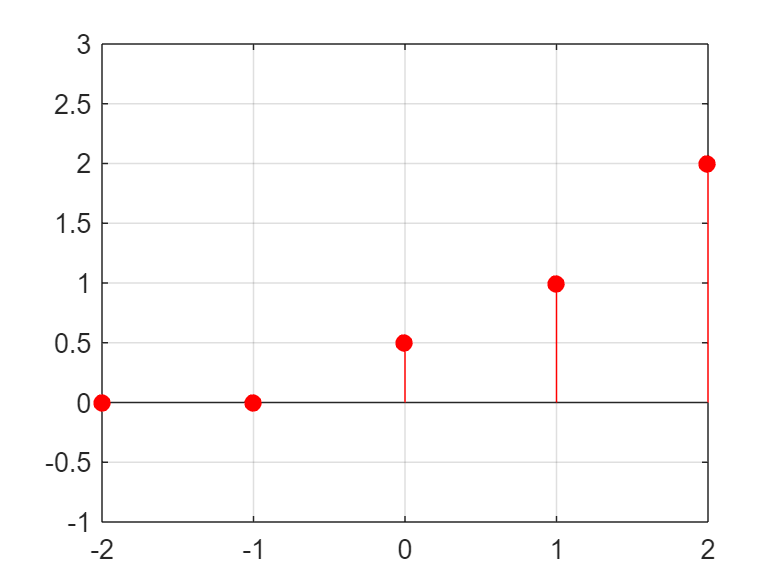

clc,clear,close all;
n = -2:1:2;
y = 0.5 * [0 0 1 0 0] + [0 0 0 1 0] + 2 * [0 0 0 0 1];
figure
stem(n,y,'r','filled'),grid on,ylim([-1 3]);

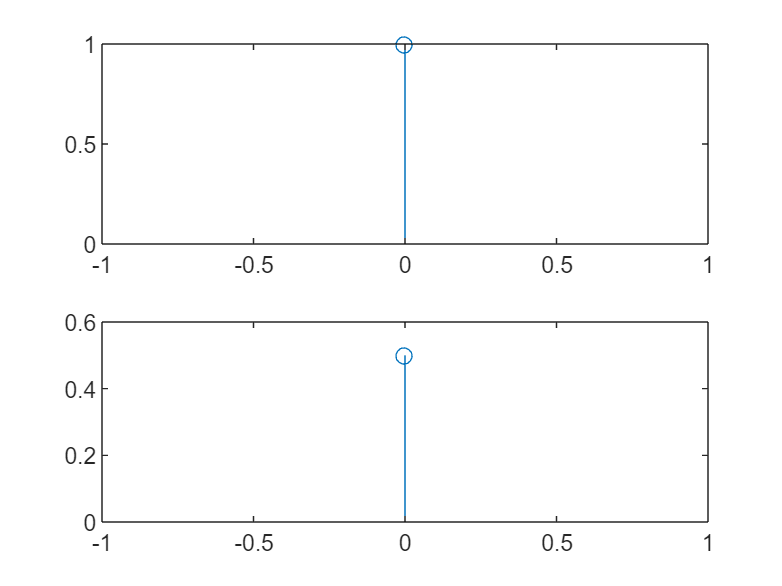

clc,clear,close all;
a = [1];
b = [0.5 1 2];
x = [1];
nx = 0;
y = filter(b,a,x);
figure
subplot(2,1,1),stem(nx,x);
subplot(2,1,2),stem(nx,y);

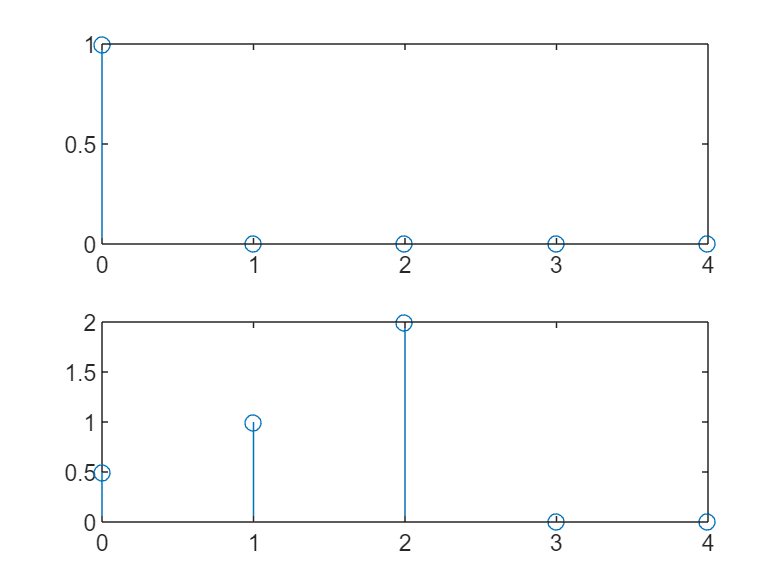

clc,clear,close all;
a = [1];
b = [0.5 1 2];
x = [1 0 0 0 0];
nx = 0:4;
y = filter(b,a,x);
figure
subplot(2,1,1),stem(nx,x);
subplot(2,1,2),stem(nx,y);

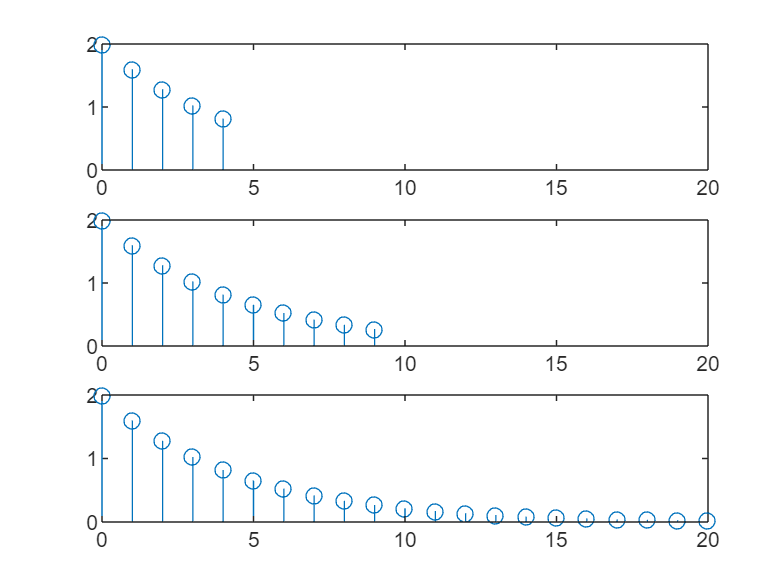

clc,clear,close all;
a = [1 -0.8];
b = [2];
x1 = [1 0 0 0 0];
nx1 = 0:4;
y1 = filter(b,a,x1);
x2 = [1 0 0 0 0 0 0 0 0 0];
nx2 = 0:9;
y2 = filter(b,a,x2);
x3 = [1 zeros(1,20)];
nx3 = 0:20;
y3 = filter(b,a,x3);
figure
subplot(3,1,1),stem(nx1,y1),axis([0 20 0 2]);
subplot(3,1,2),stem(nx2,y2),axis([0 20 0 2]);
subplot(3,1,3),stem(nx3,y3),axis([0 20 0 2]);